function dx = rr_dynamics(t,x,flag,m1,m2,L1,L2,Fv,tau,g)
% x = [q1; q2; dq1; dq2]

q1  = x(1);
q2  = x(2);
dq1 = x(3);
dq2 = x(4);

c1 = cos(q1);
c2 = cos(q2);
s2 = sin(q2);
c12 = cos(q1+q2);

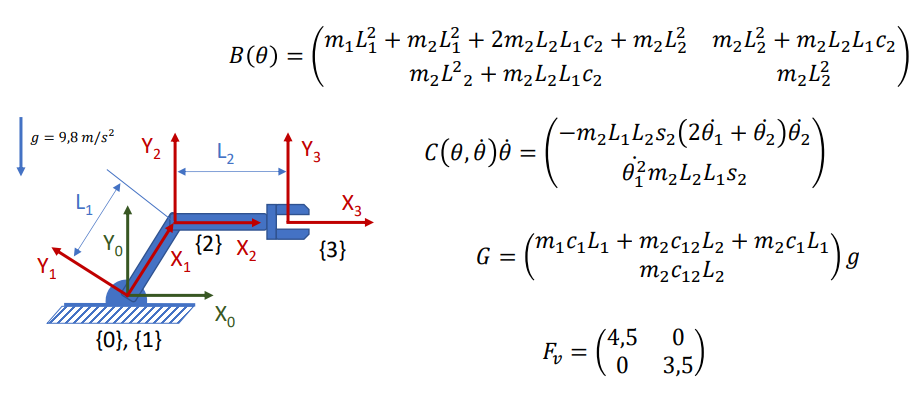

% B(q)
B = [
        m1*L1^2 + m2*L1^2 + 2*m2*L1*L2*c2 + m2*L2^2  ,  m2*L2^2 + m2*L2*L1*c2 ;
        m2*L2^2 + m2*L2*L1*c2                        ,  m2*L2^2            
    ];

% C(q,dq)*dq
C = [ 
            -m2*L2*L1*s2*(2*dq1 + dq2)*dq2;
            dq1^2*m2*L2*L1*s2
        ];

% G(q)
G = [ 
        (m1*c1*L1 + m2*c12*L2 + m2*c1*L1)*g;
        (m2*c12*L2)*g 
    ];

% Fv*dq
Fv_dq = Fv * [dq1; dq2];

% ddq
ddq = B \ (tau - C - G - Fv_dq);

dx = [dq1; dq2; ddq(1); ddq(2)];
end